## Import Data

clear all;
clc;
data = readtable("step_multiple_45to50_75ohm.csv");
data = fillmissing(data,'nearest');
data([1,2],:) = [];
data_test = readtable("step_multiple_60to70_75ohm.csv");
data_test = fillmissing(data,'nearest');
data_test([1,2],:) = [];

% Step info
step_bot=45;
step_top=50;

## Assign Variables

% Seperate values
t = table2array(data(:,1))+20;
ADC = round(table2array(data(:,2))/5*1024);
OCR = table2array(data(:,3));

% Match to duty cycle
OCR = round(OCR/5)*(step_top-step_bot)+step_bot;

t_test = table2array(data_test(:,1))+20;
ADC_test = round(table2array(data_test(:,2))/5*1024);
OCR_test = table2array(data_test(:,3));

% Match to duty cycle
OCR_test = round(OCR_test/5)*10+60;

% Find index before step
%idx = find(OCR<46,1,'last')

% Trim data with new index
%t = t(idx-9:end);
%ADC = ADC(idx-9:end);
%OCR = OCR(idx-9:end);

% Reset time and find sampling time
t = t-t(1);
T_s=t(2)-t(1)

T_s = 0.0156

## Plot Real Data

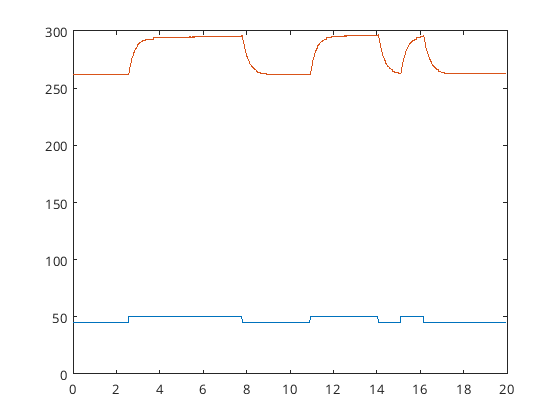

clf;
plot(t,OCR)
hold on
plot(t,ADC)
hold off

clf

## Identify Transfer Functions

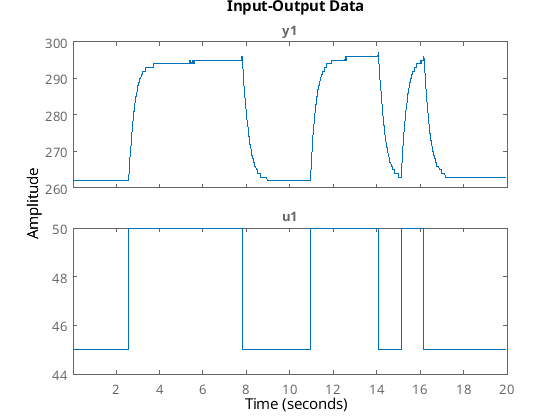

idd = iddata(ADC,OCR,T_s);
idd_test = iddata(ADC_test,OCR_test,T_s);

plot(idd)

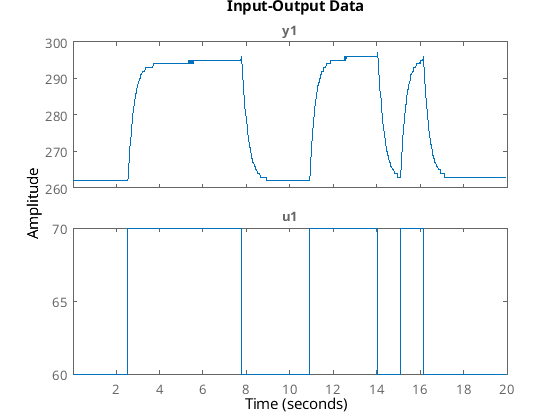

plot(idd_test)

G=tfest(idd,2,0)

G =
 
  From input "u1" to output "y1":
          2924
  ---------------------
  s^2 + 130.7 s + 497.9
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                         
Estimated using TFEST on time domain data "idd".
Fit to estimation data: 89.02%                  
FPE: 2.73, MSE: 2.709                           


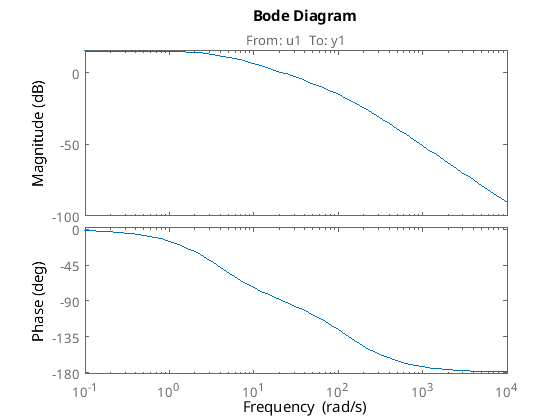

bode(G)

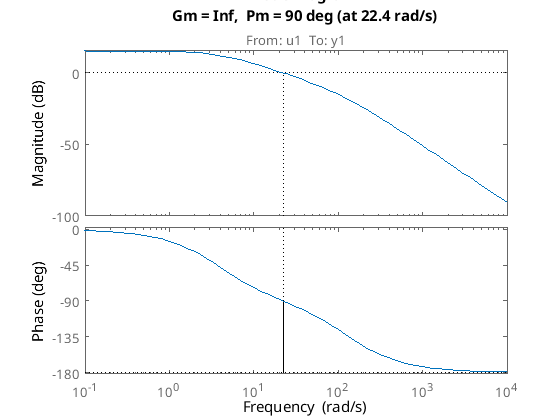

margin(G)

dcgain(G)

ans = 5.8718

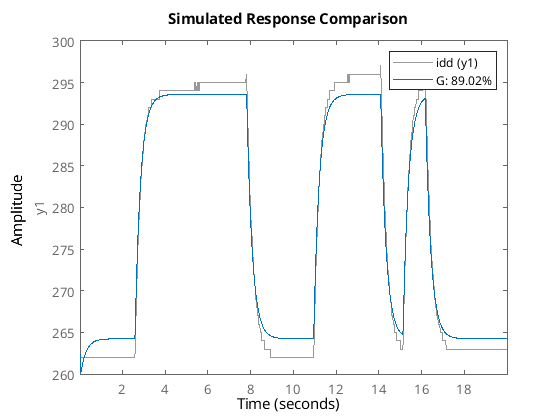

compare(idd,G)  % Passer meget godt med dataet

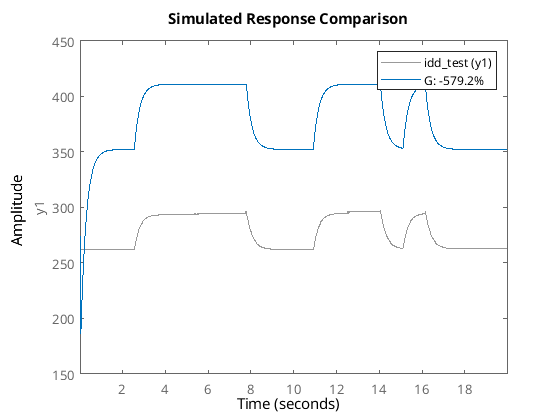

compare(idd_test,G)

## Create PID Controller

abs(pole(G))

ans =    24.1339
    2.6981


gm = 60; Ni=2.5; alpha=1.5;
%[wc, Kp, ok] = findp(G,gm);
[wc, Kp, taui, taud, ok] = findpid(G, gm, Ni, alpha)

ans = 'Found 1 valid solution(s) out of 1 phase crossing(s)'

wc = 7.3344

Kp = 0.4717

taui = 0.3409

taud = 0.1113

ok = 1

s=tf('s');
%Cpid=Kp   
Cpid=Kp*(taui*s+1)/(taui*s)*(taud*s+1)/(alpha*taud*s+1)

Cpid =
 
  0.0179 s^2 + 0.2133 s + 0.4717
  ------------------------------
      0.05692 s^2 + 0.3409 s
 
Continuous-time transfer function.
Model Properties


[numpid, denpid] = tfdata(Cpid, 'v')

numpid =     0.0179    0.2133    0.4717


denpid =     0.0569    0.3409         0


%Cpid = minreal(Cpid)
Gol=minreal(G*Cpid)

Gol =
 
  From input to output "y1":
        149.4 s^2 + 1781 s + 3938
  -------------------------------------
  s^4 + 32.82 s^3 + 225.8 s^2 + 389.9 s
 
Continuous-time transfer function.
Model Properties


Gcl=minreal(Gol/(1+Gol))

Gcl =
 
  From input "y1" to output "y1":
           149.4 s^2 + 1781 s + 3938
  -------------------------------------------
  s^4 + 32.82 s^3 + 375.2 s^2 + 2171 s + 3938
 
Continuous-time transfer function.
Model Properties


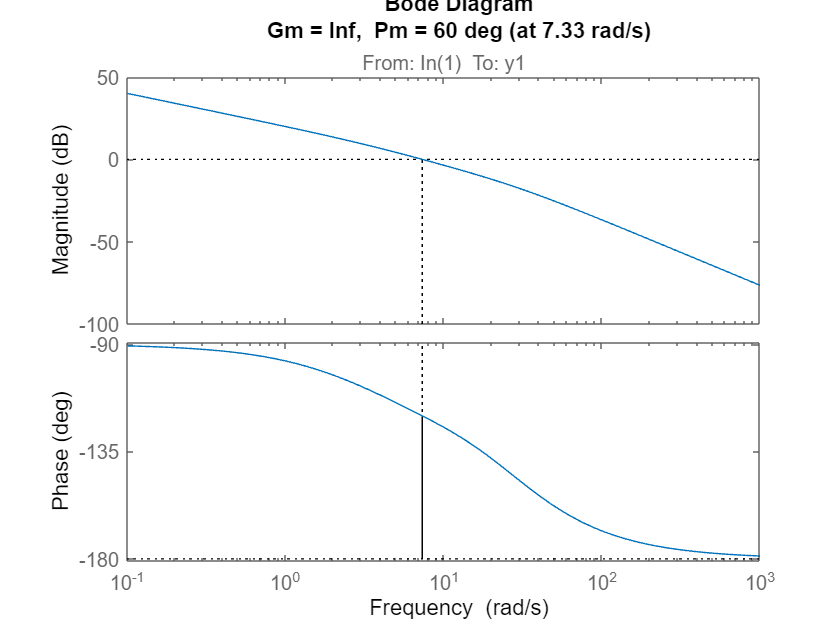

margin(Gol);

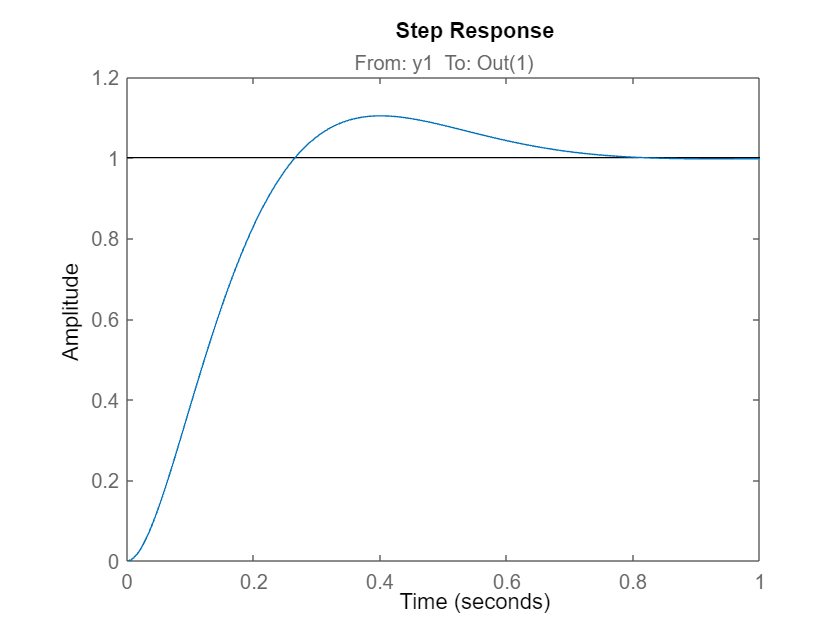

step(1*Gcl);

## Z-Transform

Gz=c2d(Cpid,1/10e3,'tustin');
Gz.Variable= 'z^-1'

Gz =
 
  0.3146 - 0.6288 z^-1 + 0.3142 z^-2
  ----------------------------------
     1 - 1.999 z^-1 + 0.9994 z^-2
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties



[num, den] = tfdata(Gz, 'v')

num =     0.3146   -0.6288    0.3142


den =     1.0000   -1.9994    0.9994


open_system('pidTF2Code.slx')
%stepz([num],[den]);

## Discrete Implementation

% Build time vector
dt=1/10e3;
t = 0:dt:14;

% Build step input
u = ones(size(t));
u(1:5)=0;

% Initialize values
y = zeros(size(t));

% Step through time and solve the difference equation
for i = 5:length(t)
        uvals = num(1)*u(i)+num(2)*u(i-1)+num(3)*u(i-2)+num(4)*u(i-3)+num(5)*u(i-4);
        yvals = -den(2)*y(i-1)-den(3)*y(i-2)-den(4)*y(i-3)-den(5)*y(i-4);
        y(i) = uvals + yvals;
end

Index exceeds the number of array elements. Index must not exceed 3.


scatter(t,y,3)